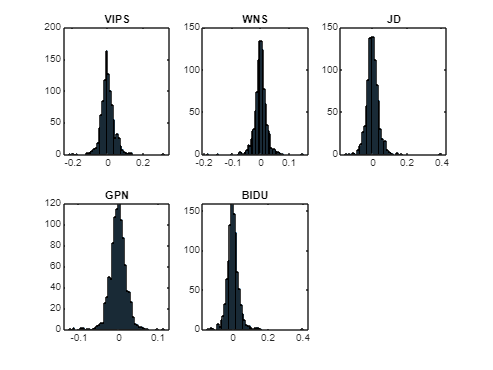


% T-Copula based CVar Portfolio Optimization ( Monthly Updated 1.4 - S.A. Holdings by K. Tomov ) 

clear; close all; clc; rng(0);

T=readtable("portfoliolist.xlsx"); %External CSV file with daily portolio log-returns.

symbol = {'VIPS', 'WNS','JD', 'GPN', 'BIDU'};
nAsset = numel(symbol);
ret = tick2ret(T{:,symbol});

function AssetScenarios = simEmpirical(ret,nScenario)

[nSample,nAsset] = size(ret);
u = zeros(nSample,nAsset);
for i = 1:nAsset
    u(:,i) = ksdensity(ret(:,i),ret(:,i),'function','cdf');
end

[rho, dof] = copulafit('t',u); %Gaussian Copula method can be integrated instead of 't'

r = copularnd('t',rho,dof,nScenario);

AssetScenarios = zeros(nScenario,nAsset);
for i = 1:nAsset
    AssetScenarios(:,i) = ksdensity(ret(:,i),r(:,i),'function','icdf');
end
end

function plotAssetHist(symbol,ret)
figure
nAsset = numel(symbol);
plotCol = 3;
plotRow = ceil(nAsset/plotCol);
for i = 1:nAsset
    subplot(plotRow,plotCol,i);
    histogram(ret(:,i));
    title(symbol{i});
end
end

plotAssetHist(symbol,ret)

nScenario = 3000; %monte carlo integration
simulationMethod = 'Empirical' %Switches Asset Covariance Matrix 

simulationMethod = 'Empirical'

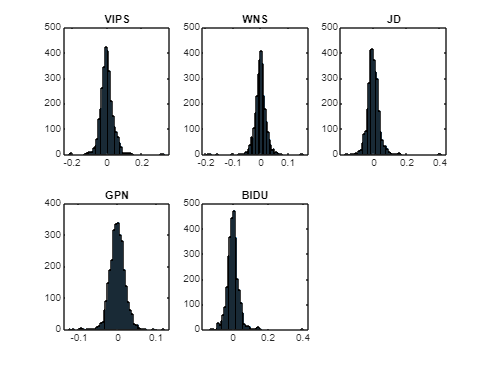

function AssetScenarios2 = simEmpirical2(ret,nScenario)

[nSample,nAsset] = size(ret);
u = zeros(nSample,nAsset);
for i = 1:nAsset
    u(:,i) = ksdensity(ret(:,i),ret(:,i),'function','cdf');
end

[rho, dof] = copulafit('t',u);

r = copularnd('t',rho,dof,nScenario);

AssetScenarios2 = zeros(nScenario,nAsset);
for i = 1:nAsset
    AssetScenarios2(:,i) = ksdensity(ret(:,i),r(:,i),'function','icdf');
end
end


switch simulationMethod %function that switches model processing parameters (Additional constraints can be added) 
    case 'Normal'% Based on normal distribution
        AssetScenarios2 = mvnrnd(mean(ret),cov(ret),nScenario);
    case 'Empirical' % Based on empirical distribution using t-copula
        AssetScenarios2 = simEmpirical2(ret,nScenario);
end

plotAssetHist(symbol,AssetScenarios2)

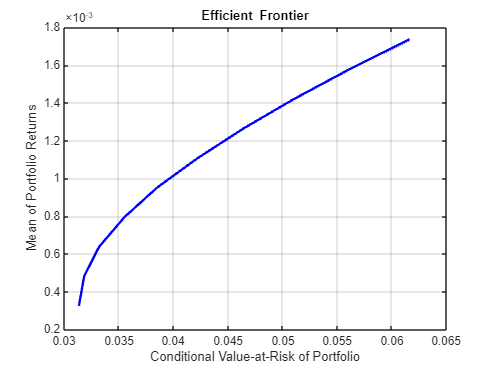

p1 = PortfolioCVaR('Scenarios', AssetScenarios2);
p1 = setDefaultConstraints(p1); 
p1 = setProbabilityLevel(p1, 0.90); 

figure;
w1 = estimateFrontier(p1);
plotFrontier(p1,w1);

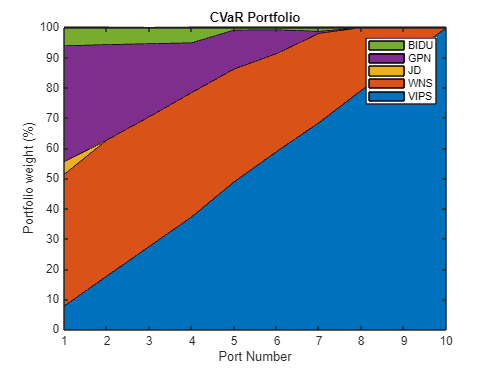

function plotWeight(w, symbol, title1)
% Function to plot portfolio weights for each portfolio number (scenarios)
figure;
w = round(w'*100,1);
area(w);
ylabel('Portfolio weight (%)')
xlabel('Port Number')
title(title1);
ylim([0 100]);
legend(symbol);
end

plotWeight(w1, symbol, 'CVaR Portfolio');

portNum = 7

portNum = 7

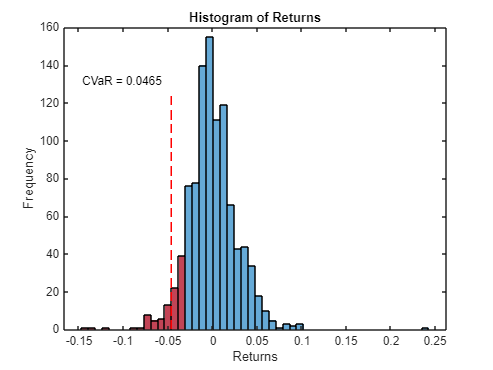

function plotCVaRHist(p, w, ret, portNum, nBin)
% Function to plot histogram of returns by highlighting the bins with value lower than VaR in red using the vertical line to indicate the CVaR level portfolio returns given portNum
portRet = ret*w(:,portNum); 
% Calculated VaR and CVaR of the portfolios.
VaR = estimatePortVaR(p,w(:,portNum));
CVaR = estimatePortRisk(p,w(:,portNum));
% Converted positive number to negative number
VaR = -VaR; 
CVaR = -CVaR;
% Ploted main histogram
figure;
h1 = histogram(portRet,nBin);
title('Histogram of Returns');
xlabel('Returns')
ylabel('Frequency')
hold on;
% < VaR level in red
edges = h1.BinEdges;
counts = h1.Values.*(edges(1:end-1) < VaR);
h2 = histogram('BinEdges',edges,'BinCounts',counts);
h2.FaceColor = 'r';
% CVaR line
plot([CVaR;CVaR],[0;max(h1.BinCounts)*0.80],'--r')
% CVaR text
text(edges(1), max(h1.BinCounts)*0.85,['CVaR = ' num2str(round(-CVaR,4))])
hold off;
end

plotCVaRHist(p1, w1, ret, portNum, 50)

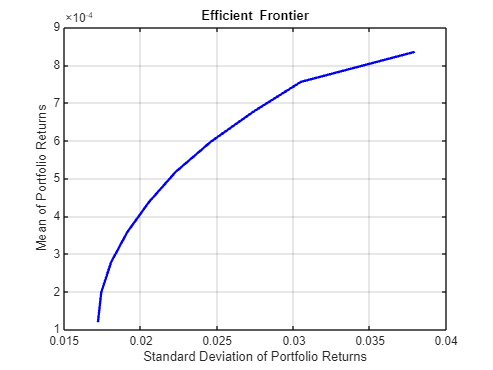

%mean variance optimization (standard method) 

p2 = Portfolio;
p2 = setAssetList(p2, symbol);
p2 = estimateAssetMoments(p2, ret);
p2 = setDefaultConstraints(p2);

w2 = estimateFrontier(p2);
plotFrontier(p2,w2);

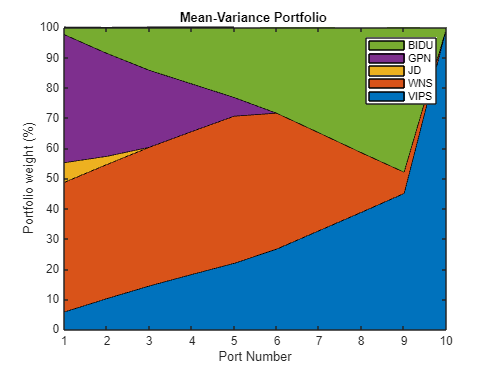

plotWeight(w2, symbol, 'Mean-Variance Portfolio ');

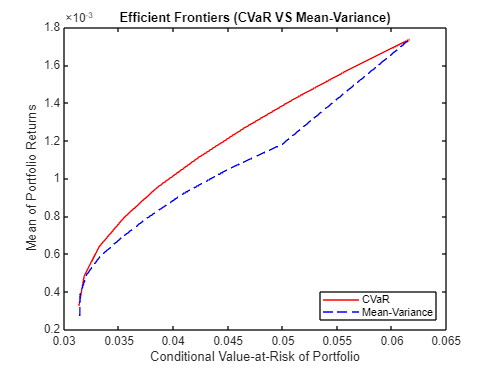

pRet1 = estimatePortReturn(p1,w1);
pRisk1 = estimatePortRisk(p1,w1);
pRet2 = estimatePortReturn(p1,w2);
pRisk2 = estimatePortRisk(p1,w2);

figure
plot(pRisk1,pRet1,'-r',pRisk2, pRet2,'--b')
title('Efficient Frontiers (CVaR VS Mean-Variance)');
xlabel('Conditional Value-at-Risk of Portfolio');
ylabel('Mean of Portfolio Returns');
legend({'CVaR','Mean-Variance'},'Location','southeast')

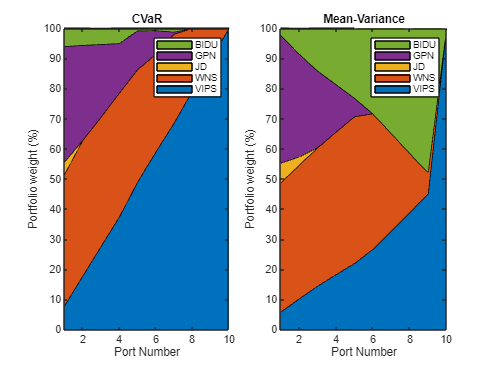

function plotWeight2(w1, w2, symbol)
figure;
subplot(1,2,1)
w1 = round(w1'*100,1);
area(w1);
ylabel('Portfolio weight (%)')
xlabel('Port Number')
title('CVaR');
xlim([1 10])
ylim([0 100]);
legend(symbol);
subplot(1,2,2)
w2 = round(w2'*100,1);
area(w2);
ylabel('Portfolio weight (%)')
xlabel('Port Number')
title('Mean-Variance');
xlim([1 10])
ylim([0 100]);
legend(symbol);
end

%comparison weights output in function of porfolio size (CVAR vs Standard mean variance model)

plotWeight2(w1, w2, symbol)